# The Gauntlet Challenge

**Authors: Dexter Friis-Hecht, Dokyun Kim, Ellen Sun**

Using the data from the Neato's LiDAR sensor, create a map of the gauntlet. Then, program it to safely navigate itself to the 'Barrel of Benevolnce' while avoiding all obstacles. 

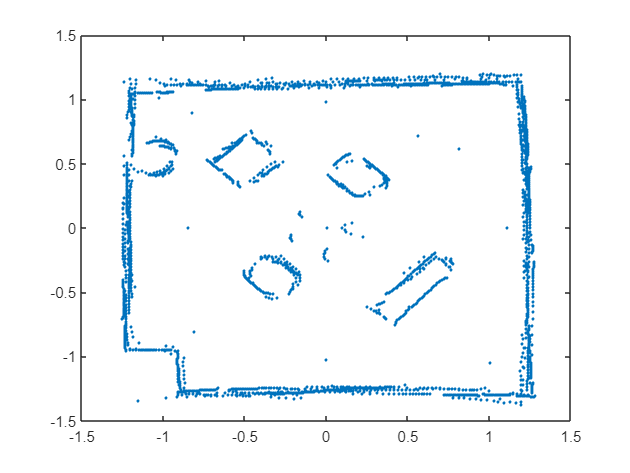

warning('off')
close all, clear all, clc

% Load LiDAR data
load('map.mat')

% Rotate to match given orientation
all_points = all_points.*-1;
data_cart = all_points';
% Convert cartesian to polar
[t,rho] = cart2pol(data_cart(:,1),data_cart(:,2));
data = [rho rad2deg(t)];
% Display the scanned map of Gauntlet
figure()
plot(data_cart(:,1),data_cart(:,2),".")
hold on;

## Using Random sample consensus (RANSAC) to identify lines

!!! Re-run previous section before re-running this section !!!

In order to identify the walls and obstacles, we need to find lines in the laser scans using a line-fitting technique. 

There are methods like linear regression and principal component analysis, but these methods are highly vulnerable to outliers.

The RANSAC algorithm is often used for identifying lines in LiDAR scans since it is robust in the presence of outliers.

RANSAC follows the steps described below:

- Select two random points from the dataset to define a line.

- Split the remaining points into two groups: Inliers & Outliers

- Repeat the 2 steps above $n$ times

- Keep the line with most inliers

The code below will find 35 lines in the dataset using the `find_RANSAC` function.

First parameter is the dataset used, second parameter is the inlier threshold, and the third parameter is the number of random selection. 

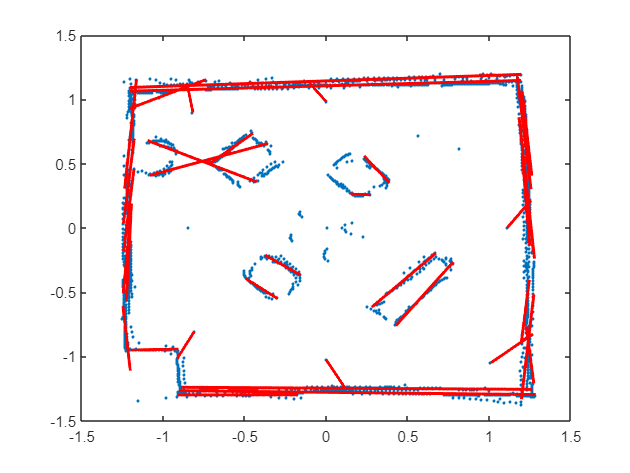

% Run RANSAC
iter = 35;

% Initialize array
m_array = ones(iter,1);
b_array = ones(iter,1);
ep1s = ones(iter,1);
ep2s =ones(iter,1);


for i = 1:iter
    % Do RANSAC 'iter' times
    [m_b,ends,inlier,outlier,bestfit_point,polar]=find_RANSAC(data,0.015,10000);
    m_array(i) = m_b(1);
    b_array(i) = m_b(2);
    ep1s(i)=ends(1,1);
    ep2s(i)=ends(2,1);

    % Plot line
    x = linspace(ends(1,1),ends(2,1));
    y = m_b(1)*x+m_b(2);
    plot(x,y,'r',LineWidth=2)

    % Remove inliers, repeat RANSAC with new data
    [t,rho]=cart2pol(outlier(:,1),outlier(:,2));
    data = [rho rad2deg(t)];
end
hold off;

## Potential Fields

To make the Neato avoid obstacles while pathing towards the barrel, we can give the lines defining the object negative potential while giving the barrel a potisive potential. In a 3D space, the obstacles will appear as deep troughs while the barrel will appear as a deep valley. 

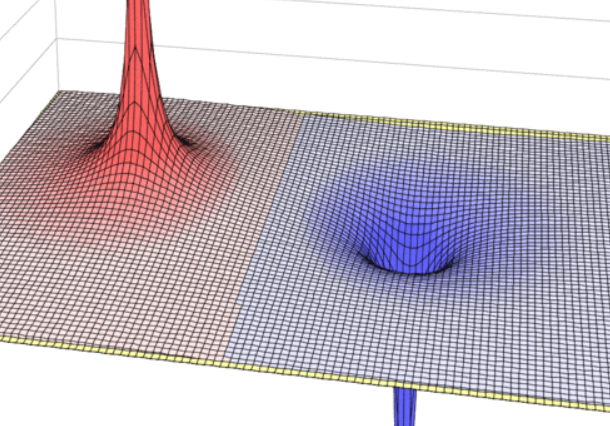

The gauntlet will have multiple of the red peaks and exactly one blue valley. Using the gradient descent algorithm used in `Flatlands`, we can guide the Neato towards the barrel while avoiding the obstacles.

To give a line $y =  mx+b$ negative potential, we need to sum up all the potential fields created by the points on the line. 

The potential field due to a point (a,b) is defined by


$$V(x,y) = k*log\sqrt{(x-a)^2+(y-b)^2}$$


where $k=1$ gives a negative potential, and $k=-1 $ gives a positive potential.

To evaluate this function for every point along a line, we need to use a line integral.

The line integral of a function$f$ along a curve $C$ is expressed as


$$\int_C f dl$$


The most robust way to evaluate this is parametrizing C with $x(t)$ and $y(t)$. Think about $x(t)$ and $y(t)$ as the position of a particle that is moving along the curve from t = a to t = b. Then, the differential $dl$ is the **distance** the particle moves along the curve during a small timestep $dt$.


$$dl = \sqrt{(\frac{dx}{dt})^2+(\frac{dy}{dt})^2} dt$$


Then, the line integral can be reduced to be in terms of time.


$$\int_c fdl = \int_Cf((x(t),y(t))\sqrt{(\frac{dx}{dt})^2+(\frac{dy}{dt})^2} dt$$


The steps to evaluate the potential field function along a line $y = mx+b$ with endpoints $(x_1,y_1),(x_2,y_2)$ is shown below.

- Parametrize the line segment into $a(t) = t$ and $b(t) = mt+b$, $x_1 \leq t \leq x_2$

- We then get $\frac{da}{dt} = 1$ and  $\frac{db}{dt} = m$

- Substitute into line integral: $V_C(x,y) = \int_{x_1}^{x_2}log\sqrt{(x-t)^2+(y-(mt+b))^2}*\sqrt{1-m^2} dt$

The code below will calculate the potential fields of all the lines found by RANSAC in the previous section using the `line_potential` function.

pots = [];
for i = 1:iter
% Potential field for lines identified by RANSAC
    m = m_array(i);
    b = b_array(i);
    ep1 = ep1s(i);
    ep2 = ep2s(i);
    [potential,Xp,Yp]=line_potential(m,b,ep1,ep2);
    
    if i == 1
        X = Xp;
        Y = Yp;
        pots = potential;
    else
        pots = pots + potential;
    end
end

### Barrel of Benevolence (BoB)

To add the Barrel's potential field, we now need to do an integral along a circle instead of a line. 

The approach is similar:

Given a circle $(x-x_c)^2+(y-y_c)^2=r^2$ where $(x_c,y_c)$ is the center and $r$ is the radius, we can parametrize it into

$a = rcos(t)$ and $b=rsin(t)$, $0 \leq t \leq 2\pi$ which gives

$\frac{da}{dt} = -rsin(t)$ and $\frac{db}{dt} = rcos(t)$

Plugging in the new $a,b$,$\frac{da}{dt}$ and $\frac{db}{dt}$ into the integral gives


$$V_C(x,y) = \int_{0}^{2\pi}log\sqrt{(x-rcos(t))^2+(y-rsin(t))^2}*r dt$$


The code below calculates the barrel's potential field using its position (-1.1,0.5) and radius of 0.14.

% Potential field of BoB
[pot_circ,x,y] = circ_potential(-1.1,0.5,0.14);
pots = pots+pot_circ;

### Accounting for Error

Due to the random aspect of RANSAC, some objects are not identified by RANSAC. We manually add the potential fields of these obstacles using the code below.

% Array of x&y positions of missing lines' endpoints
x_array = [
            -0.455,-0.173412,-1.2625,-1.2875,1.225; 
            -0.263, -0.305,1.15,-1.2375, 1.275
            ];
y_array = [
            0.747,-0.36,1.075,1.05,1.0875;
            0.515,-0.533,1.1,-1.3,-1.275
            ]

y_array =     0.7470   -0.3600    1.0750    1.0500    1.0875
    0.5150   -0.5330    1.1000   -1.3000   -1.2750


% Potential field for missing lines
for i=1:length(x_array)
    x1=x_array(1,i);
    y1=y_array(1,i);
    x2=x_array(2,i);
    y2=y_array(2,i);
    
    
    a = y1-y2;
    b = -(x1-x2);
    c = x1*y2-x2*y1;
    
    
    new_m = -a/b;
    new_b = -c/b;
    [pot,~,~] = line_potential(new_m,new_b,x1,x2);
    pots = pots + pot;
end

### Guiding points

The gradient descent algorithm will provide the path towards the barrel. However, the algorithm does not take the Neato's size into account, making the Neato collide into obstacles even though the path seems correct. We add some guiding potential fields along the generated path to prevent the Neato from colliding with obstacles.

point_guides = []


point_guides =

     []



for i = 1:length(X)
    x = X(1,i);
    for j = 1:length(Y)
        y = Y(j, 1);
        point_guides(j,i) = -700 * (log(sqrt((x-0.8375).^2+(y-.5).^2)) + log(sqrt((x-0.4625).^2+(y-.05).^2)) + log(sqrt((x-0.65).^2+(y-.2375).^2)) + log(sqrt((x-0.05).^2+(y+.5).^2)) + log(sqrt((x-.2875).^2+(y+.35).^2)));
    end
end

pots = pots + point_guides;


## Visualizing the 'peaks' and 'troughs'

Now we can plot the gradient map and visualize the gauntlet as a massive potential field. The brighter gradient means positive potential, and the darker gradient means negative potential.

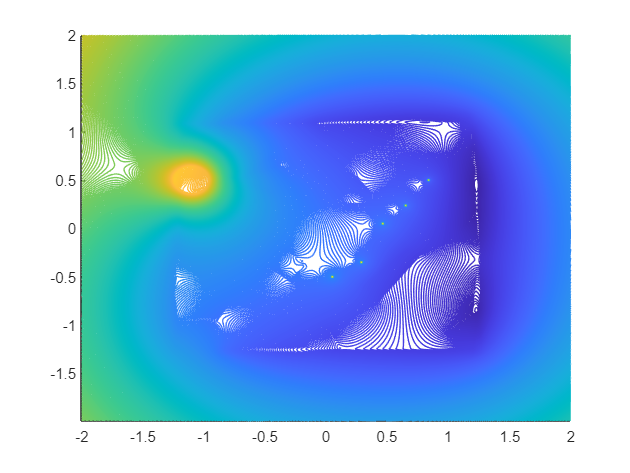

figure()
hold on;
contour(X,Y,pots,500)
[dx,dy] = gradient(pots);
axis([-2 2 -2 2])
hold off;

## Gradient ascent for path planning

With the potential field of the gauntlet, we can now calculate the path towards the barrel with a gradient ascent algorithm that was also used in the Flatland challenge.

% Initial values
x_i = 0.933;
y_i = 0.838;
x_arr = [x_i; 0]; %Matrix to store x positions
y_arr = [y_i; 0]; %Matrix to store y positions

lambda = 0.03;
delta = 0.37;



max_steps = 15;
curr_step = 1;

x_idx = find(abs(X(1,:) - x_i) < (0.0125/2));
y_idx = find(abs(Y(:,1) - y_i) < (0.0125/2));
grad_i = [dx(y_idx, x_idx); dy(y_idx, x_idx)];

% Calculate Neato path with gradient ascent
% Store the x,y positions of each step in a matrix
while abs(norm(grad_i)) > 0.00001 && curr_step <= max_steps
    curr_step = curr_step + 1;
    if x_i < -1.3
        x_i = -1.3;
    end
    if x_i > 1.1
        x_i = 1.1;
    end
    if y_i > 1.1
        y_i = 1.1;
    end
    if y_i < -1.2
        y_i = -1.2;
    end
    x_idx = find(abs(X(1,:) - x_i) <= (0.0125/2));
    y_idx = find(abs(Y(:,1) - y_i) <= (0.0125/2));
    grad_i = [dx(y_idx, x_idx); dy(y_idx, x_idx)]; %Update gradient
    x_i = x_i + lambda*grad_i(1); %Find next x
    y_i = y_i + lambda*grad_i(2); %Find next y
    lambda = delta * lambda; %Update lambda
    x_arr(curr_step) = x_i;
    y_arr(curr_step) = y_i;
end

## Plot with planned path

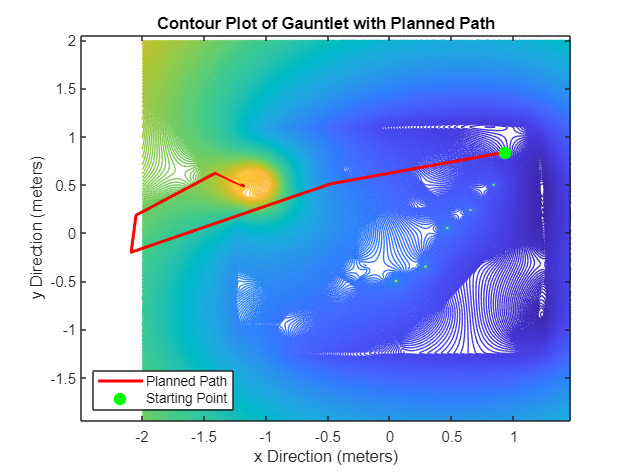

figure()
contour(X,Y,pots,500)
hold on
plot(x_arr, y_arr, "r", "LineWidth", 2)
start_x = 0.933;
start_y = 0.838;
plot(start_x, start_y, "g.", "MarkerSize", 25)
legend("", "Planned Path", "Starting Point","Location", "Southwest")
xlabel("x Direction (meters)")
ylabel("y Direction (meters)")
title("Contour Plot of Gauntlet with Planned Path")
hold off
axis([-2 2 -2 2]);